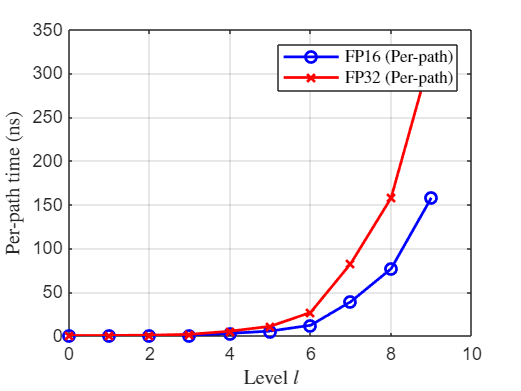

T = readtable('mlmc_path_timings_10.csv'); %taken from C++ timing benchmarks - payoff_path_timings.cpp
level=0:1:9;

% Levels (handy for plotting)
levels = T.M;     % [1 2 4 8 ...]
h      = T.h;

% Per-path (ns)
PP16 = T.FP16_Path_mean_ns;
PP32 = T.FP32_Path_mean_ns;

% Per-path-step (ns)
PPS16 = T.FP16_PathStep_mean_ns;
PPS32 = T.FP32_PathStep_mean_ns;

[levels, idx] = sort(levels);
PP16  = PP16(idx);
PP32  = PP32(idx);
PPS16 = PPS16(idx);
PPS32 = PPS32(idx);


%%per-path plot
figure
plot(level,PP16,'-ob', 'LineWidth', 1.5, 'DisplayName', 'FP16 (Per-path)');
hold on
plot(level,PP32,'-xr', 'LineWidth', 1.5, 'DisplayName', 'FP32 (Per-path)');

xlabel('Level $l$','Interpreter', 'latex')
ylabel('Per-path time (ns)','Interpreter', 'latex')
legend('Location','northeast','Interpreter', 'latex')

grid on
hold off

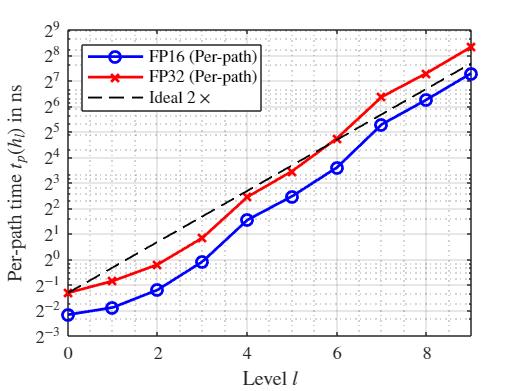



%%% Plot IDEAS
figure; hold on; grid on; box on

% data
plot(level, PP16, '-ob', 'LineWidth', 1.5);
plot(level, PP32, '-xr', 'LineWidth', 1.5);

% ---- Ideal ×2 reference (anchored at first FP32 point) ----
l0   = level(1);
y0   = PP32(1);                   
ref2 = y0 .* 2.^(level - l0);    
plot(level, ref2, '--k', 'LineWidth', 1.0);

set(gca, 'YScale', 'log');
ymin = min([PP16(:); PP32(:); ref2(:)]);
ymax = max([PP16(:); PP32(:); ref2(:)]);
kmin = floor(log2(ymin));
kmax = ceil( log2(ymax));
yt   = 2.^(kmin:kmax);
set(gca, 'YTick', yt);
set(gca, 'YTickLabel', arrayfun(@(k) sprintf('$2^{%d}$',k), kmin:kmax, ...
    'UniformOutput', false), 'TickLabelInterpreter', 'latex');

xlim([min(level) max(level)]);
ylim([2^kmin 2^kmax]);

xlabel('Level $l$', 'Interpreter', 'latex');
ylabel('Per-path time $t_p(h_l)$ in ns', 'Interpreter', 'latex');
legend('FP16 (Per-path)', 'FP32 (Per-path)','Ideal $2\times$','Location', 'northwest', 'Interpreter', 'latex');
grid minor;
hold off

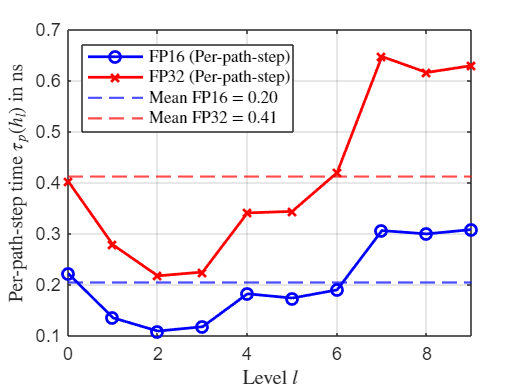



%% per-path-step plot
figure
h1 = plot(level,PPS16,'-ob', 'LineWidth', 1.5); hold on
h2 = plot(level,PPS32,'-xr', 'LineWidth', 1.5);

% Mean lines (without inline labels)
h3 = yline(mean(PPS16), '--b', 'LineWidth', 1.2);
h4 = yline(mean(PPS32), '--r', 'LineWidth', 1.2);

xlabel('Level $l$','Interpreter','latex')
ylabel('Per-path-step time $\tau_p(h_l)$ in ns','Interpreter','latex')
xlim([0 9]); grid on

% Legend with mean values included
legend([h1 h2 h3 h4], ...
    'FP16 (Per-path-step)', ...
    'FP32 (Per-path-step)', ...
    sprintf('Mean FP16 = %.2f', mean(PPS16)), ...
    sprintf('Mean FP32 = %.2f', mean(PPS32)), ...
    'Location','northwest','Interpreter','latex')